Let's start by creating some data on which to perform inference.

rng(14);
n=300;
rand1 = exprnd(0.2,[1,floor(n/3)]);
rand3 = exprnd(0.2,[1,floor(n/3)]);
rand4 = exprnd(0.2,[1,floor(n/3)]);

y = ([rand1,rand3,rand4])

y =     0.1331    0.0515    0.0278    0.9645    0.2344    0.0087    0.1335    0.2290    0.1235    0.3017    0.0430    0.2144    0.1236    1.0275    0.0792    0.3121    0.0140    0.1966    0.0569    0.0541    0.0277    0.4413    0.2407    0.1489    0.0792    0.2713    0.0710    0.0840    0.3407    0.2266    0.0239    0.4969    0.0585    0.5550    0.0625    0.0595    0.1793    0.0017    0.1588    0.3323    0.2090    0.0671    0.2058    0.5928    0.2305    0.0002    0.2490    0.1545    0.0615    0.0116


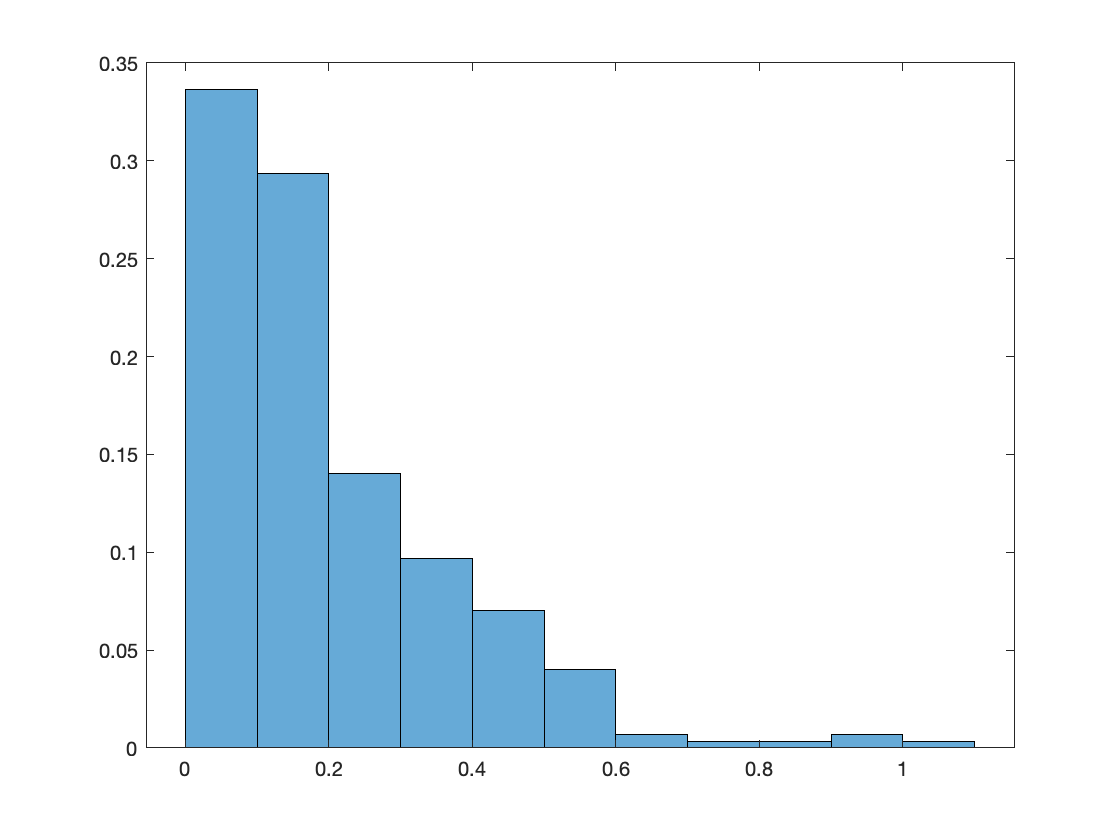

histogram(y, 'Normalization','probability')


sum(y<0)

ans = 0

sum(y>1)

ans = 1


knots = [0.0, 0.1, 0.21, 0.41, 0.6, 0.81, 1];
d = 5;
constraintFunc = @(x) logspline_constraint(knots, x);
options = optimoptions('fsolve','Display','none','TolFun', 1e-10);

flag=1;
solve_this = @(a) (constraintFunc(a));
initial = [6, 4, 3, 1, 0.5];
initial_guess = fsolve(solve_this, initial.*0.1, options)

initial_guess =     0.3988    0.1255   -0.0066   -0.1678   -0.1999


We'll select knots based on the graphic, although more principled methods exist.

% Arbitrarily choosing the starting value, with dimension parameter_dim:
data = y;
q0 = initial_guess';
nllFunc = @(x) negLog_fiducial_likelihood(knots,x,data);
conFunc = constraintFunc;

% Set parameters (that I don't quite understand)
nRuns = 1+10;
Nscale = 10000;
runTime = 15; % Time per run in seconds
nTrials = 100000;
doPrint = false;

samplers = struct([]);

h = 1e-3;
M = 1;
L = 1;
hmcOpts = struct('intMethod',0,'doPrint',doPrint,'printMod',10);
samplers(end+1).name = sprintf('CHMC (L = %d)',L);
samplers(end).desc = sprintf('M = %g, h = %g',M,h);
samplers(end).func = @(q,N) constrainedHMC(q,nllFunc,conFunc,M,N,L,h,hmcOpts);
samplers(end).N = ceil(Nscale./L);
samplers(end).style = 'b-';

samplerQs = cell(length(samplers),1+nTrials);
samplerStats = cell(length(samplers),1+nTrials);
samplerNLLs = cell(length(samplers),1+nTrials);
samplerTs = zeros(length(samplers),1+nTrials);
for i = 1:numel(samplers)
    fprintf('%s...',samplers(i).name);
    [q1,qs,samplerStats{i,1}] = samplers(i).func(q0,samplers(i).N);
    samplerQs{i,1} = [q0 qs q1];
    samplerTs(i,1) = samplerStats{i,1}.t/samplerStats{i,1}.N;
%     samplerNLLs{i,1} = nllFunc(samplerQs{i,1});
    
    currN = ceil(runTime./samplerTs(i,1));
    fprintf('%d samples: ',currN);
    fprintf('\n');
end

CHMC (L = 1)...

STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT IT

mean(samplerStats{1,1}.accepted)
Qs = samplerQs{1,1};
save("HMC_logsplineDraws.mat",'Qs');

Qs = load("HMC_logsplineDraws.mat").Qs

samples = Qs;
mean_value = mean(samples')';
mean_diff = samples - mean_value;
[~,num_cols] = size(mean_diff);
mag_mean_diff = zeros(1,num_cols);
for i=1:num_cols
    mag_mean_diff(i) = norm(mean_diff(:,i), 2);
end
[~,min_index] = min(mag_mean_diff);

chosen_theta = samples(:,min_index)

syms func(x)
func(x) = piecewise( (knots(1) < x)&(x <= knots(2)),exp(chosen_theta(1)*(x-knots(1))/(knots(2)-knots(1))), ...
                               (knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
                               (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
                               (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
                               (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
                               (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(5)*(knots(6)-x)/(knots(6)-knots(5))));

% fplot(y, [0,1])
fplot(func, [0,1])

double(int(func, 0, 1))